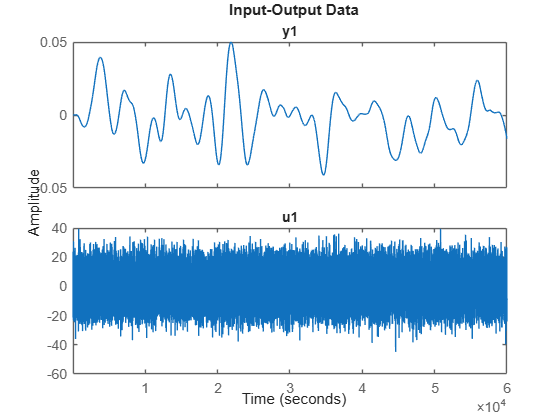

data = iddata(y,u,1);

% dados para estimação
datae = data(1:700);

% dados para validação
datav = data(701:end);

plot(data)

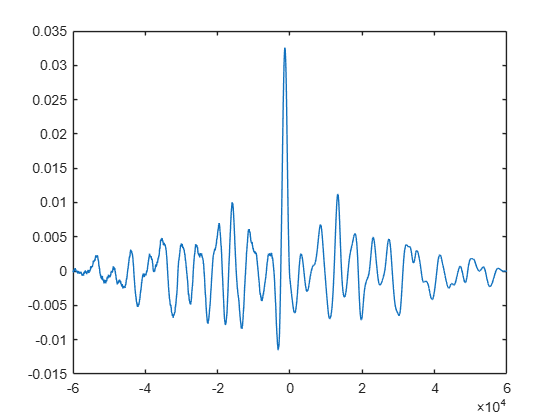

[rxy,lag] = xcorr(u,y,'coeff');
plot(lag,rxy)

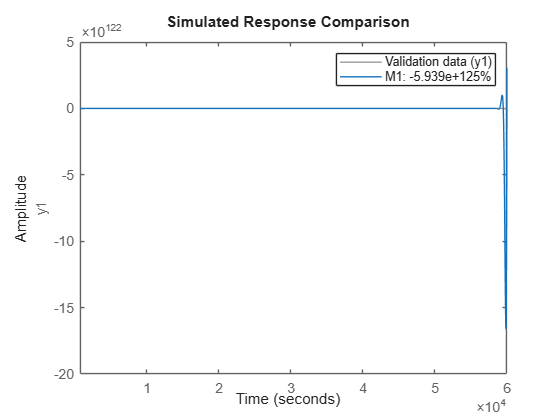


M1 = arx(datae,[2 1 3]);
compare(M1,datav)


M = tf(M1)


M =
 
  From input "u1" to output "y1":
                 -1.265e-11 z^-1
  z^(-2) * ---------------------------
           1 - 2.011 z^-1 + 1.011 z^-2
 
Sample time: 1 seconds
Discrete-time transfer function.



M2=d2c(M1)


M2 =
Continuous-time ARMAX model: A(s)y(t) = B(s)u(t) + C(s)e(t)
  A(s) = s^2 - 0.01105 s + 6.763e-05                       
                                                           
  B(s) = -6.3e-12 s - 1.258e-11                            
                                                           
  C(s) = s^2 + 1.493 s + 0.9945                            
                                                           
Input delays (listed by channel): 2                        
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=0
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
